# Three Node Network inversion with TAPAS

## Simulate resting state data for three node network

As done in Frässle et al. (2021) using function created code from SPM's `DEM_demo_induced_fMRI.m `to generate resting state time series.

stim_options = get_default_stim_options();
type = 'r'; % setting to 'r' instead of 's' until bug is fixed
cmap = mycmap();

Generate data using AR(1) process and inhibititory self-connections.

[DCM, options] = make_DEM_demo_induced_fmri(stim_options);

Visualize simulated graph and BOLD data.

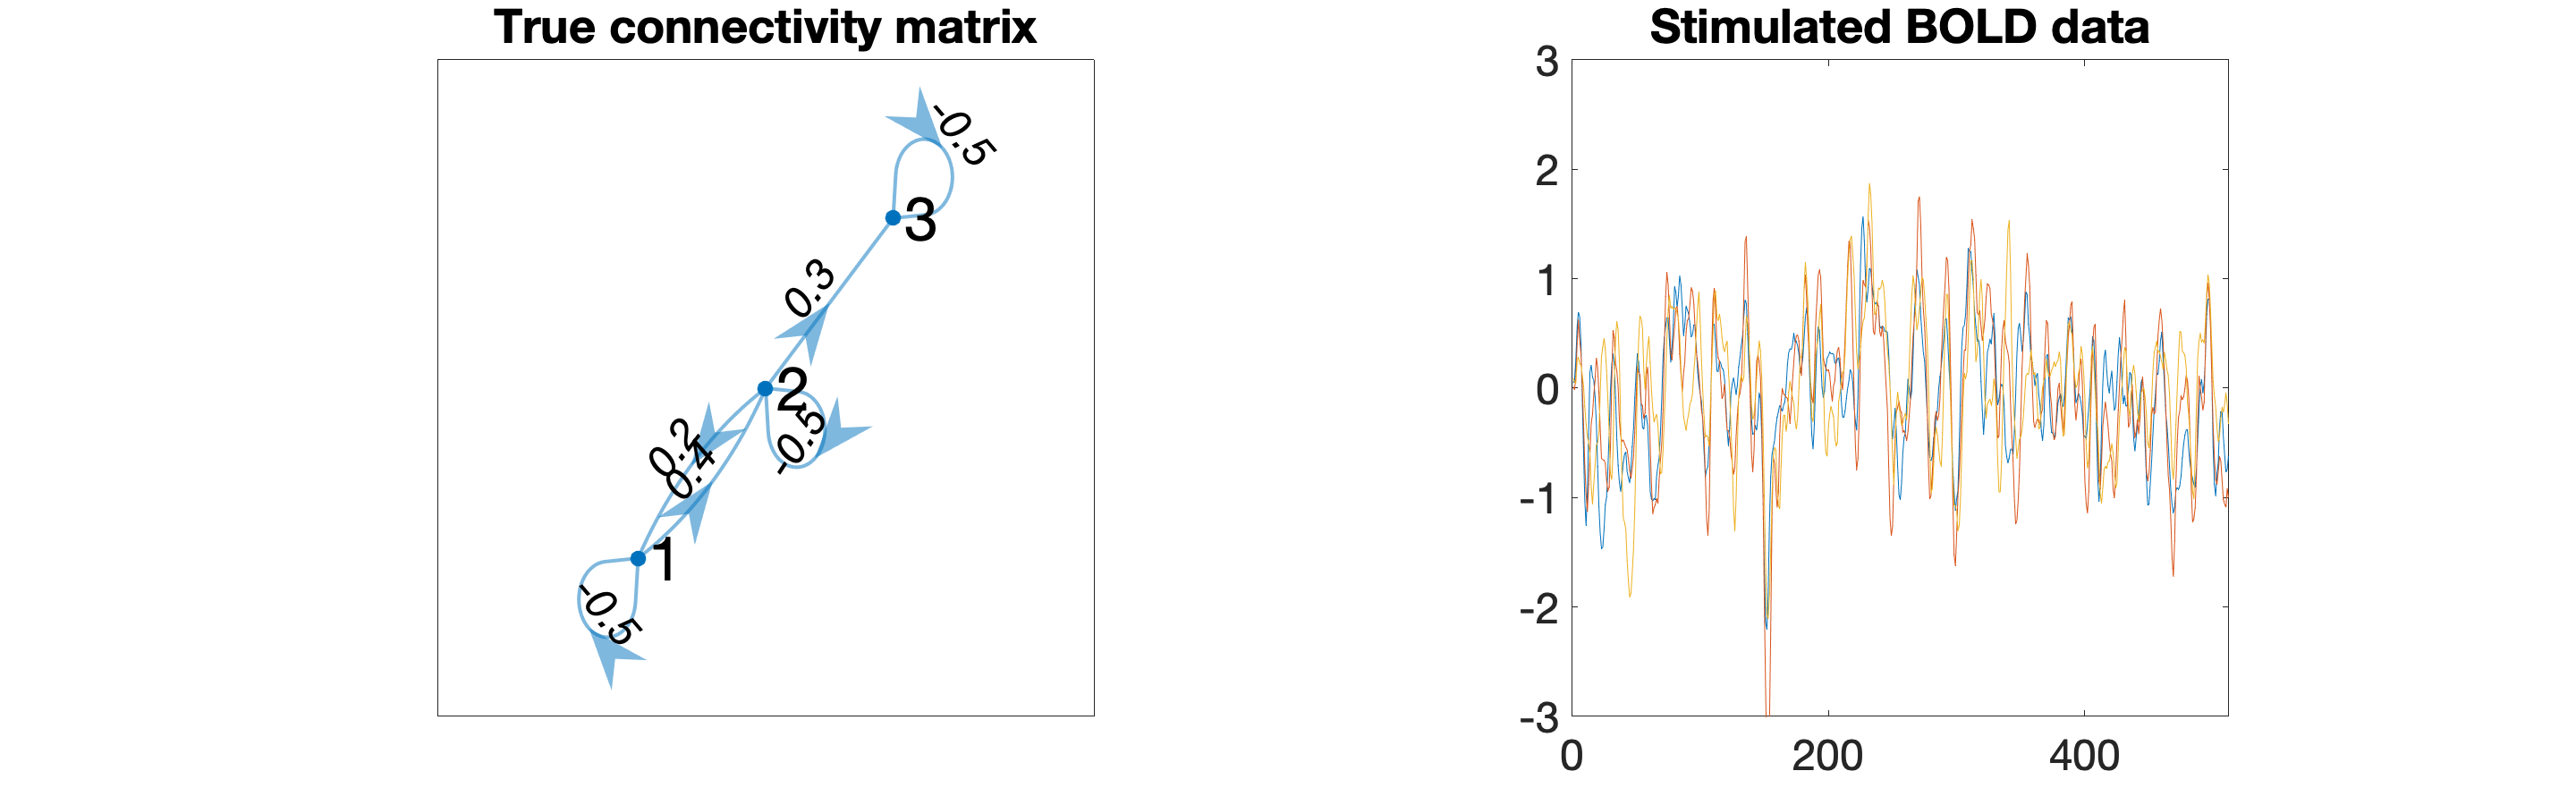

plot_sim_data(DCM)

Remove input so rDCM knows its endogenous activity and set other parameters in the structure that the functions need.

if isfield(DCM, "U")
    DCM = rmfield(DCM,'U');
end

## Invert simulated data using rDCM

### sparse rDCM estimated A

Estimate parameters pruning a fully connected adjacency matrix using `tapas_rdcm_sparse.m`

[output_sparse, options_sparse] = tapas_rdcm_estimate(DCM, type, options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


Plot results

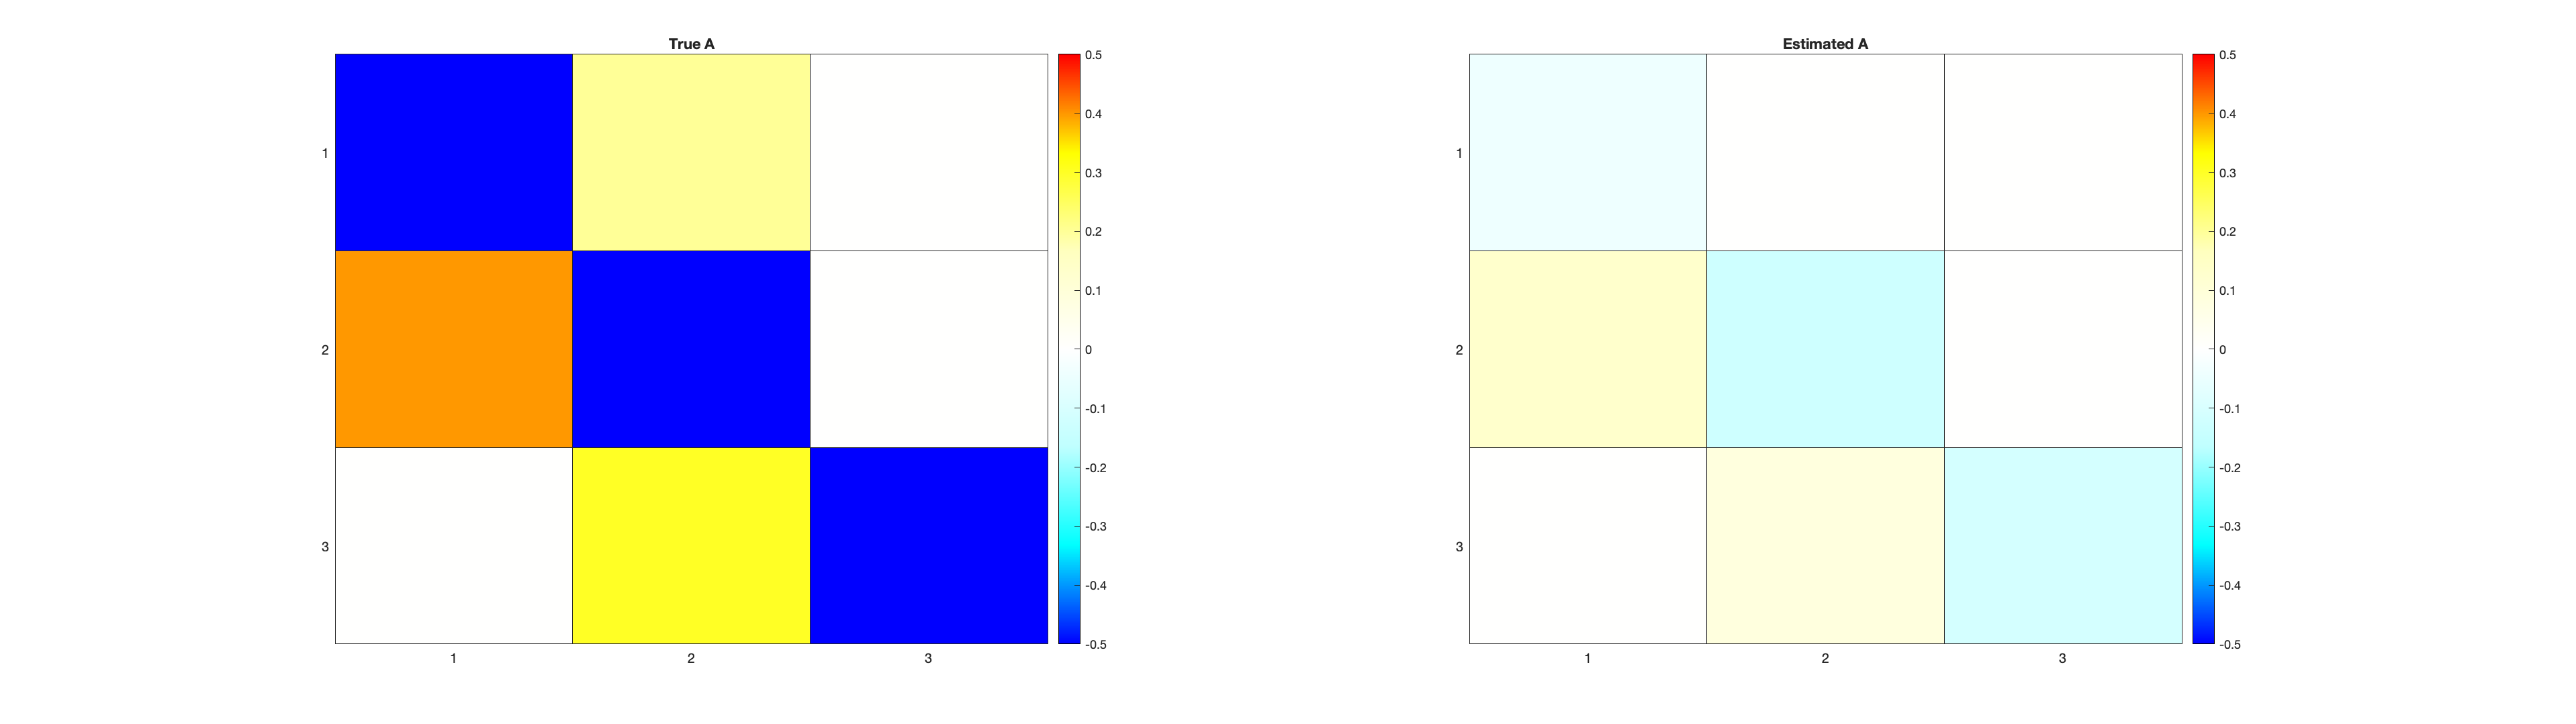

f = figure();

subplot(1, 2, 1)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A"); 

subplot(1, 2, 2)
h = heatmap(output_sparse.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("Estimated A"); 

set(f,'Units','normalized','Position',[0 0 1 .5]); 

Does it estimate anything in C?

output_sparse.Ep.C

ans =      0
     0
     0


### ridge rDCM estimated A

What if `DCM.a`, the option describing which parameters to estimate,  is not fully connected but set to `logical(pP.A)` i.e. the ridge regression is explicitly told which connections should exist?

DCM.a = logical(DCM.Tp.A);
[output_ridge, options_ridge] = tapas_rdcm_estimate(DCM, type, options, 1);


Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


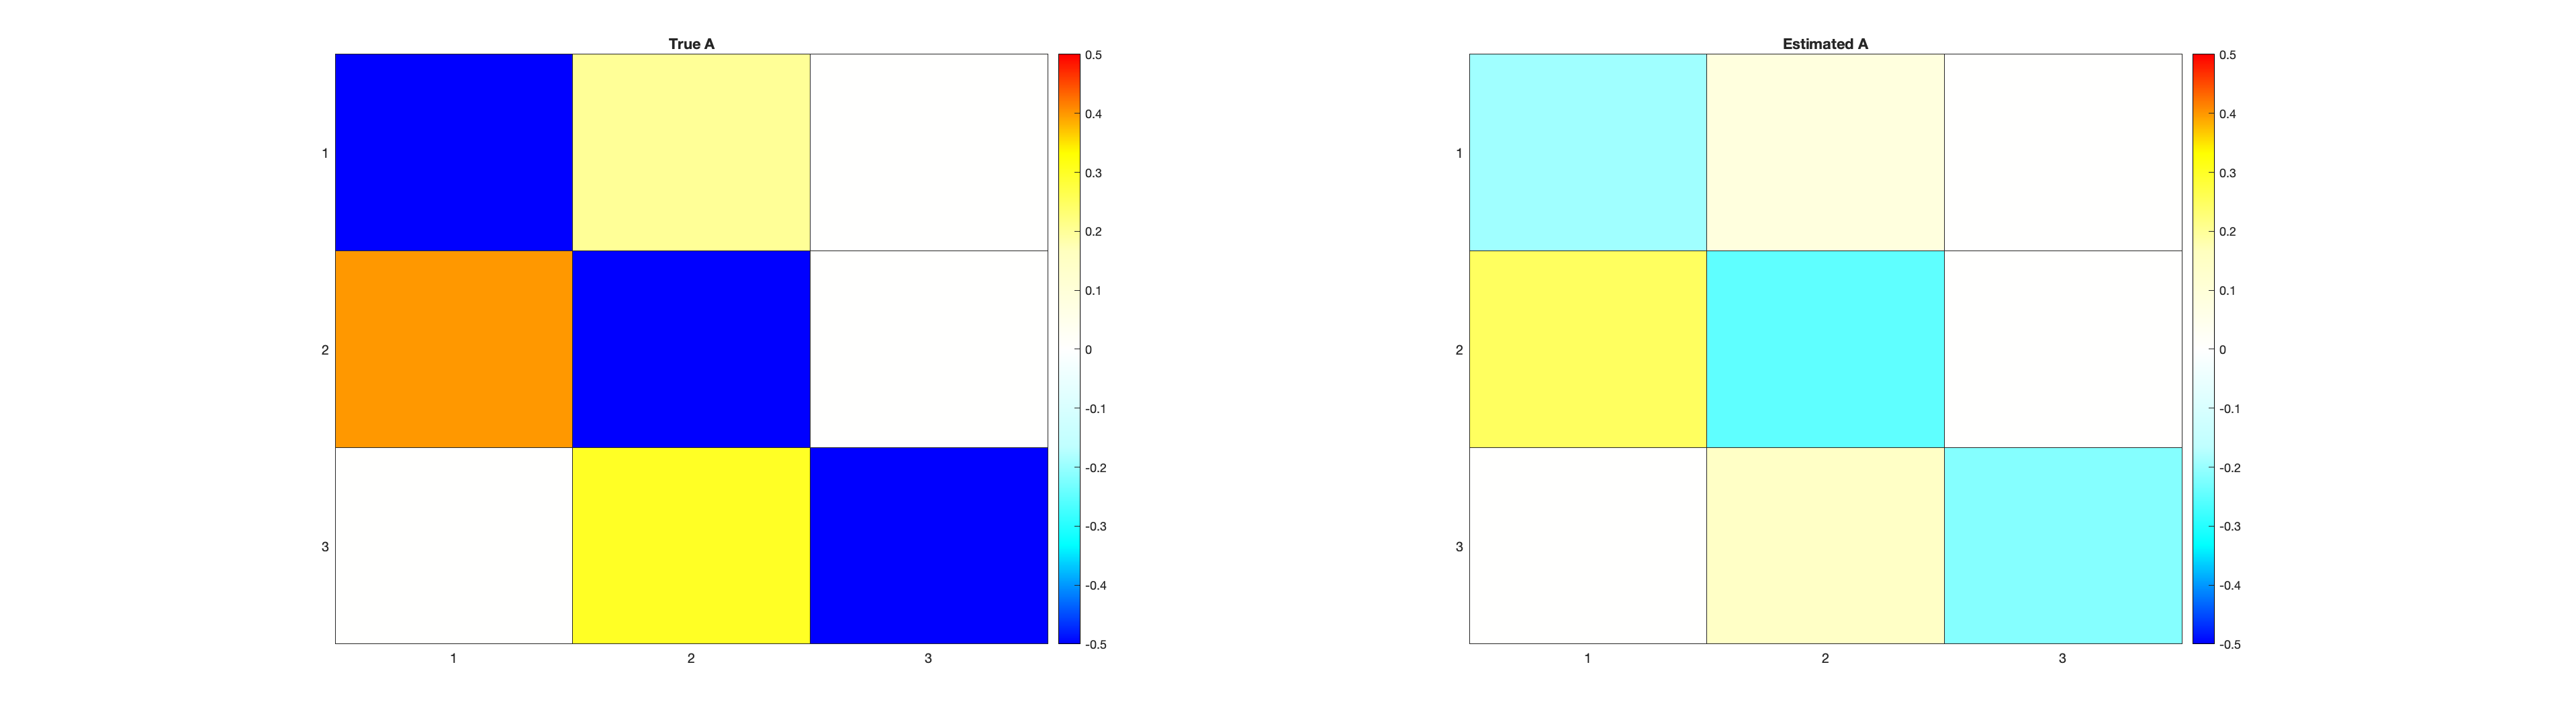

f = figure();

subplot(1, 2, 1)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A"); 

subplot(1, 2, 2)
h = heatmap(output_ridge.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("Estimated A"); 

set(f,'Units','normalized','Position',[0 0 1 .5]); 

Is there anything in C?

output_ridge.Ep.C

ans =      0
     0
     0


### Comparison of the sparse and ridge outputs

Does sparse provide a more similar connectivity matrix compared to ridge?

RMSE_sparse = get_rmse(DCM.Tp.A , output_sparse.Ep.A)

RMSE_sparse = 0.2713

RMSE_ridge = get_rmse(DCM.Tp.A , output_ridge.Ep.A)

RMSE_ridge = 0.1820

RMSE_sparse < RMSE_ridge

ans = logical
   0


Does sparse provide a better "fit" compared to deterministic ridge? 

output_sparse.logF > output_ridge.logF

ans = logical
   0


## Predicted vs. actual signal in frequency domain

Since this is a linear regression how do predicted versus actual values look for signal in the frequency domain?

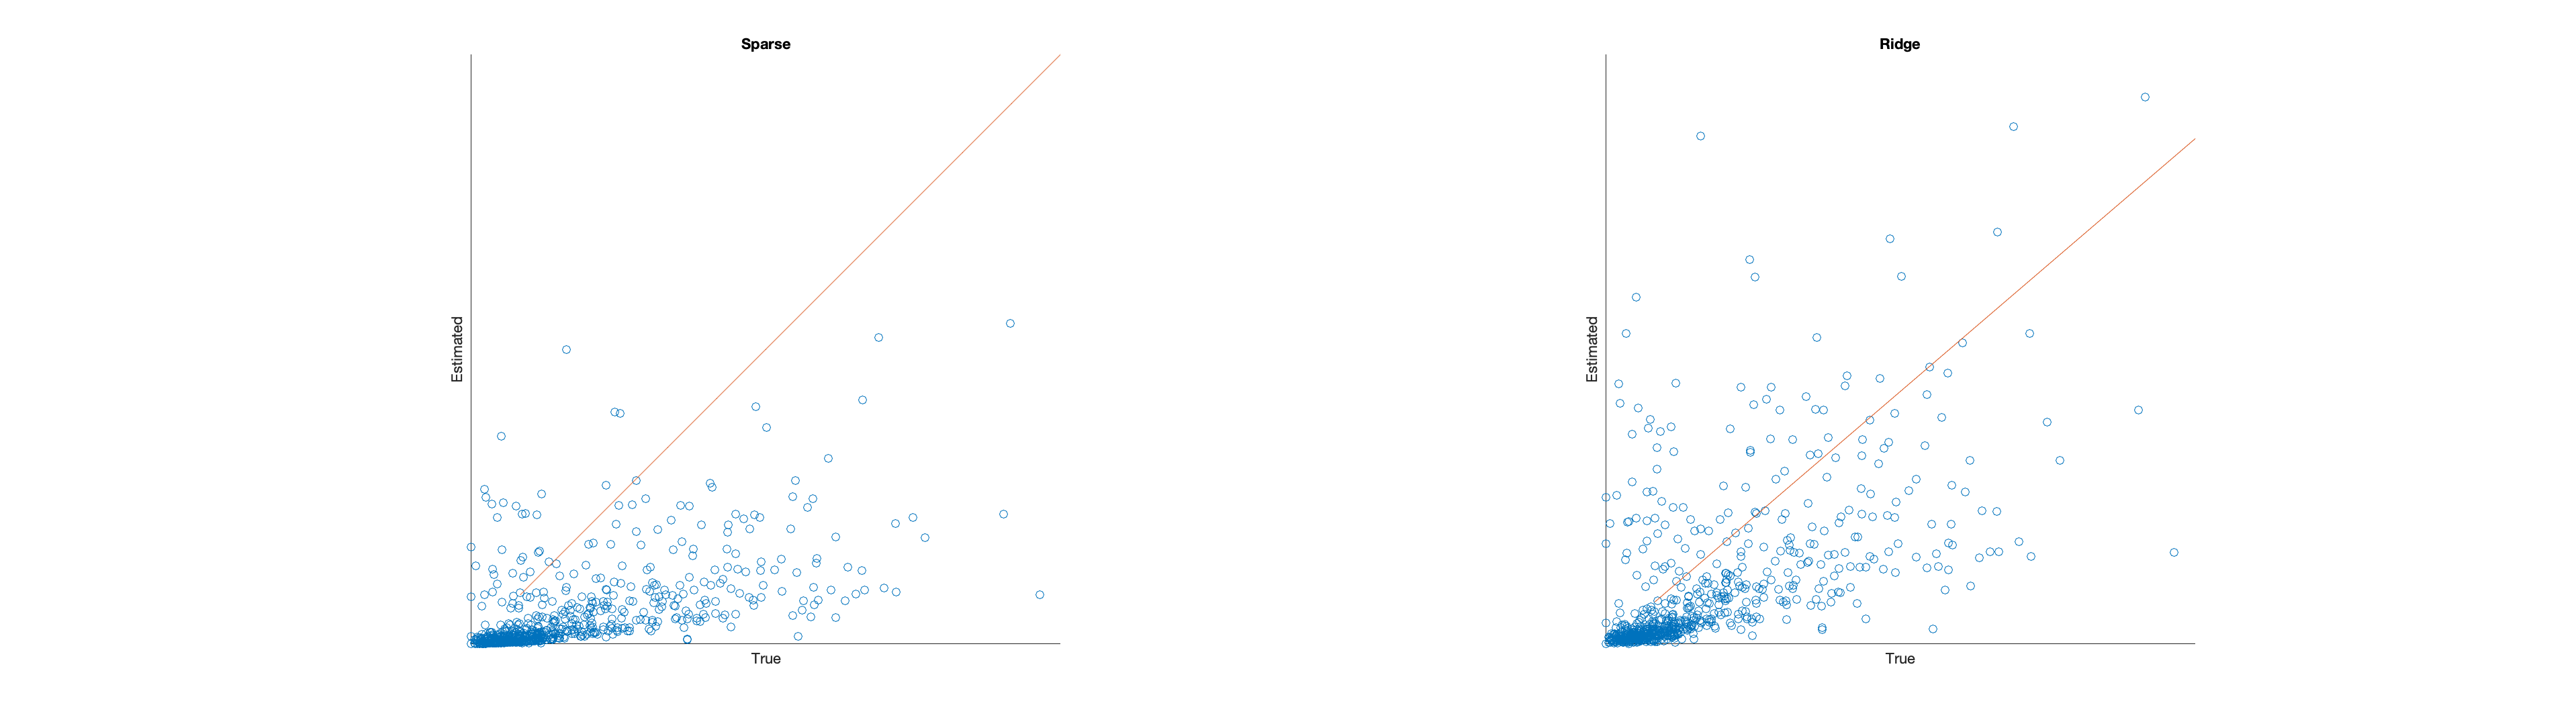

clf
fig = figure();

subplot(1, 2, 1);
scatter(abs(output_sparse.signal.yd_source_fft),abs(output_sparse.signal.yd_pred_rdcm_fft));
hold on 
plot(1:12);
axis square;
set(gca,'XTick',[]);
set(gca,'YTick',[]);
xlabel("True");
ylabel("Estimated");
title("Sparse");

subplot(1, 2, 2);
scatter(abs(output_ridge.signal.yd_source_fft),abs(output_ridge.signal.yd_pred_rdcm_fft));
hold on 
plot(1:12);
axis square;
set(gca,'XTick',[]);
set(gca,'YTick',[]);
xlabel("True");
ylabel("Estimated");
title("Ridge");

set(fig,'Units','normalized','Position',[0 0 1 .5]); 

What do the estimated signals look like in the frequency domain? (Magnitude spectrum plots)

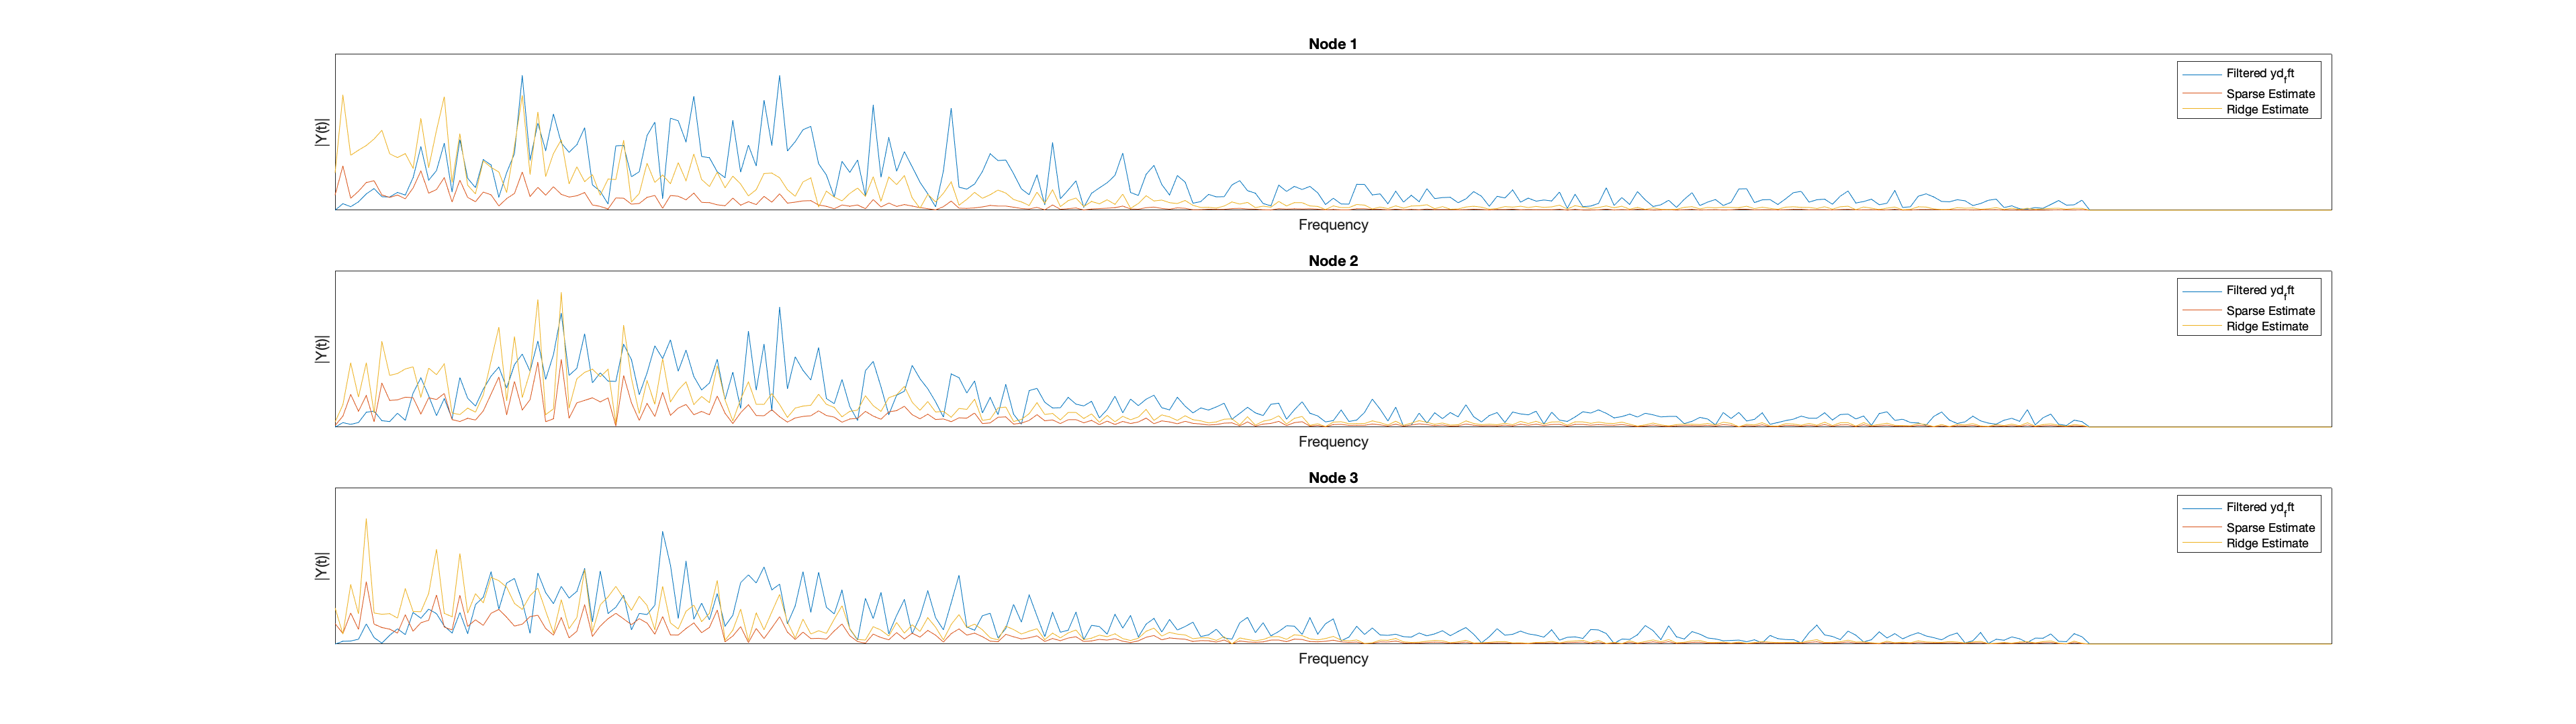

real_comps = 1:(ceil((length(DCM.Y.y)+1)/2));
Fs = options.y_dt;
sampnum = [0: max(real_comps)-1]';
f = sampnum*Fs/length(DCM.Y.y);
clf
for i = 0:(stim_options.n-1)
    subplot(stim_options.n, 1, i+1);
    cur_y = output_ridge.signal.yd_source_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    hold on
    cur_y = output_sparse.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    hold on
    cur_y = output_ridge.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    legend("Filtered yd_fft","Sparse Estimate","Ridge Estimate");
    set(gca,'XTick',[]);
    set(gca,'YTick',[]);
    title(sprintf("Node %.0f", i+1));
    ylabel('|Y(t)|');
    xlabel('Frequency');
end

How do you get from connectivity matrix to the predicted signals above? The values in the estimated connectivity matrix are the coefficients with which to multiply the columns of the design matrix. The sparse estimate is consistently lower than the true signal because the connectivity values estimates are low.

## Moving between yd_fft and y_source

Can I produce the filtered yd_fft that is the DV in the models from the original signal?

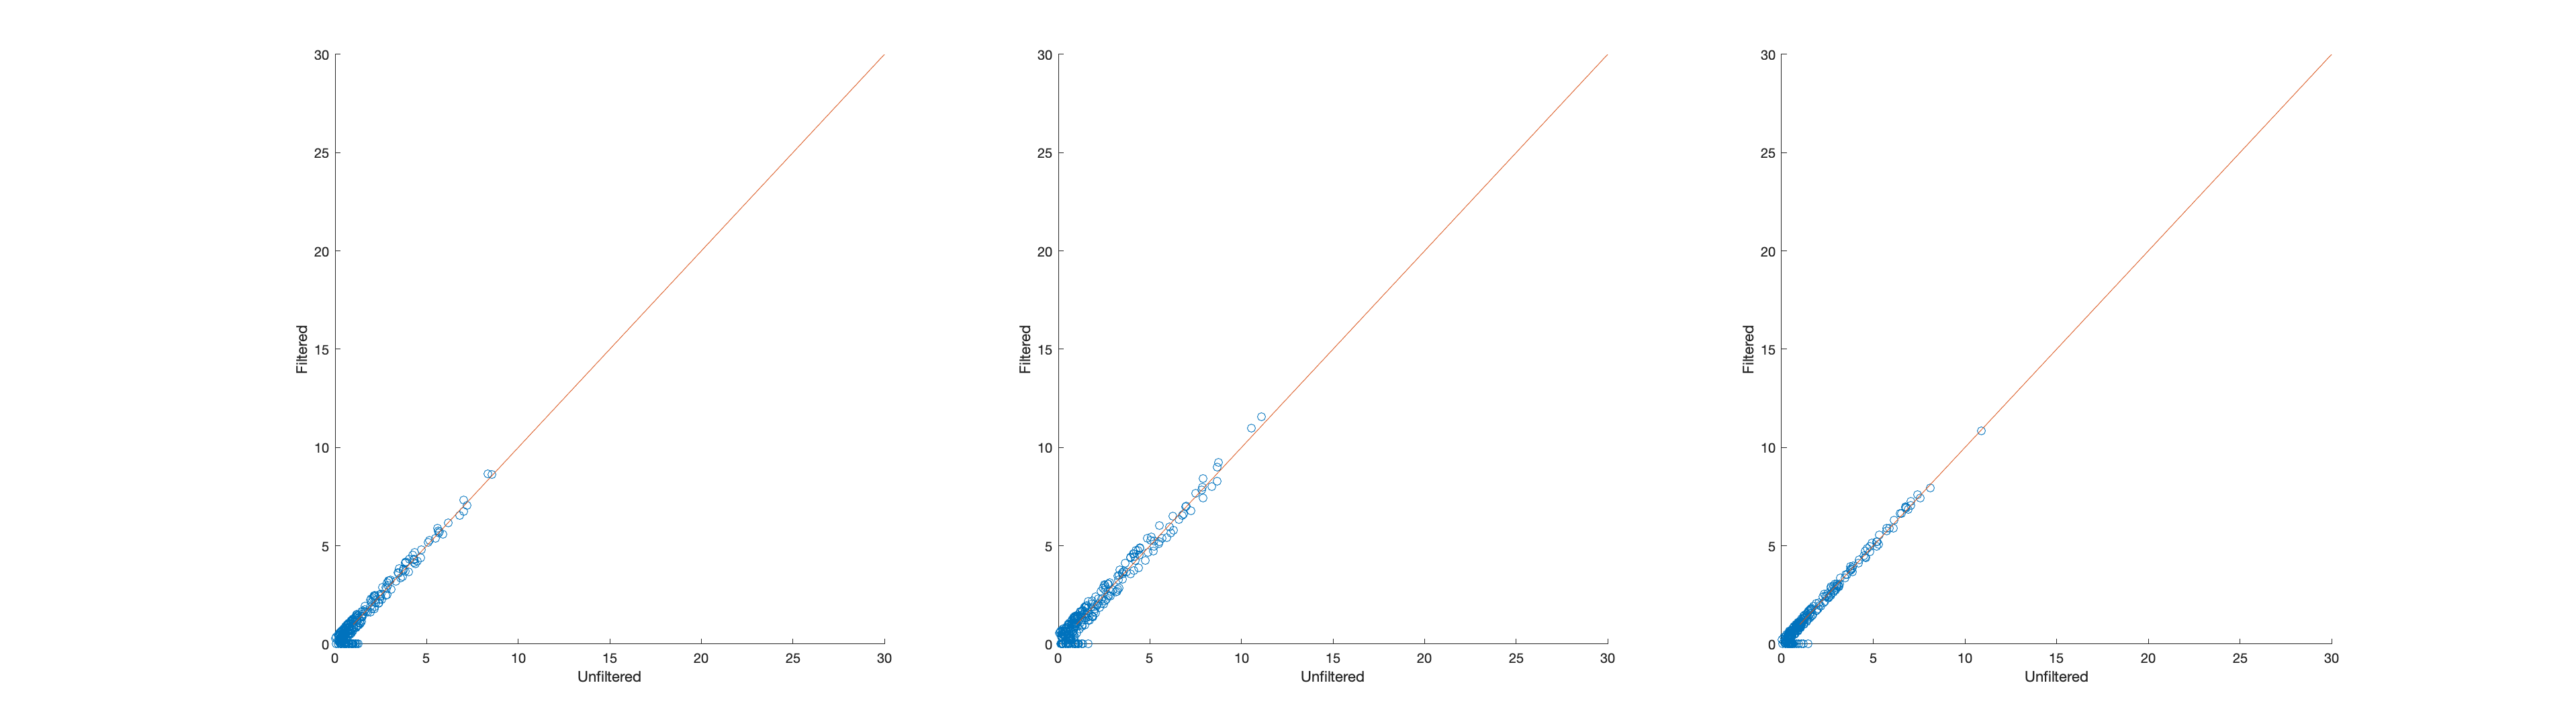

clf
for i = 0:(stim_options.n-1)
    subplot(1, stim_options.n, i+1);
    unf_yd_fft = fft([0; diff(output_ridge.signal.y_source(i*stim_options.T+1:(i+1)*stim_options.T))/stim_options.TR]);
    filt_yd_fft = output_ridge.signal.yd_source_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    scatter(abs(unf_yd_fft(real_comps)), abs(filt_yd_fft(real_comps)));
    hold on
    plot(1:30);
    xlabel('Unfiltered');
    ylabel('Filtered');
end

Can I IFFT the predicted frequency domain signals to generate predicted time series?

**Note by using the **`output.signal.yd_source_fft`** won't identically replicate **`output.signal.y_source`** because it is filtered?**

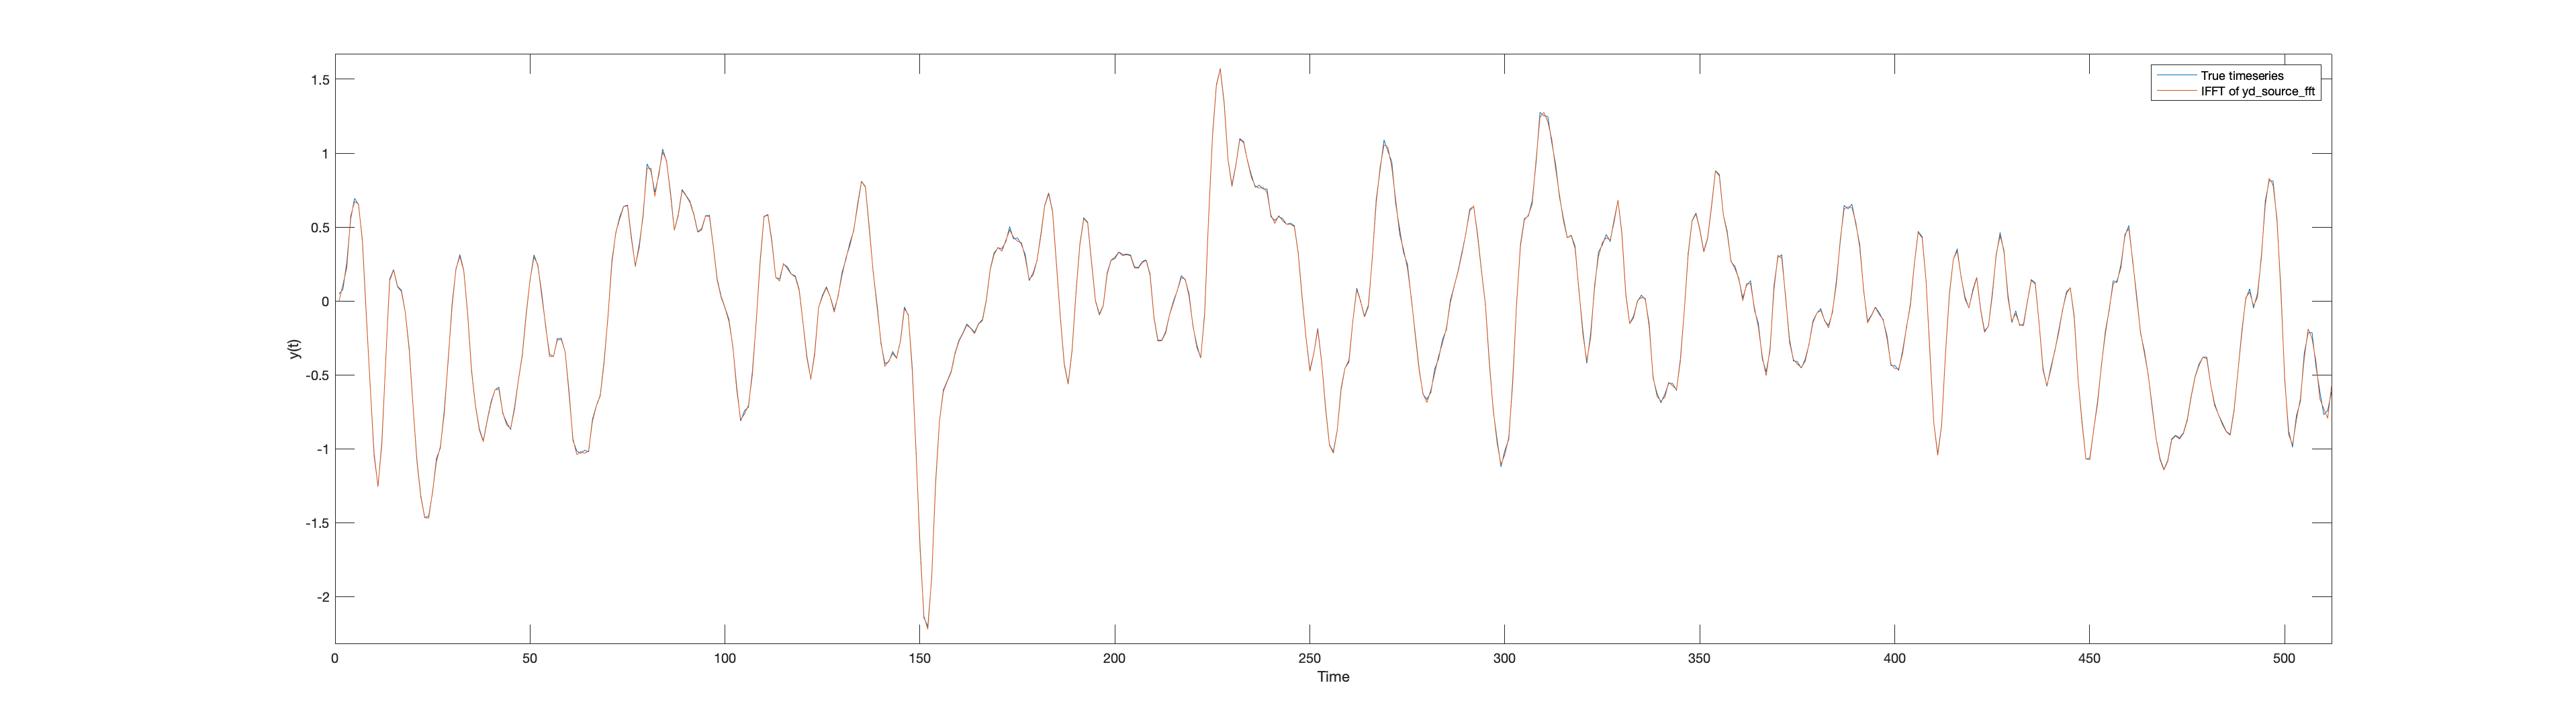

clf
plot(1:stim_options.T , output_ridge.signal.y_source(1:stim_options.T));
hold on
cur_y = stim_options.TR*real(cumsum(ifft(output_ridge.signal.yd_source_fft(1:stim_options.T))));
cur_y = [0; cur_y(1:end-1)];
plot(1:stim_options.T , cur_y);
legend("True timeseries", "IFFT of yd\_source\_fft");
axis([0 stim_options.T  min(cur_y)-0.1 max(cur_y)+0.1]);
xlabel('Time');
ylabel('y(t)');

## Predicted vs. actual signal in time domain

What do the timeseries of IFFT from the estimated frequencies look like?

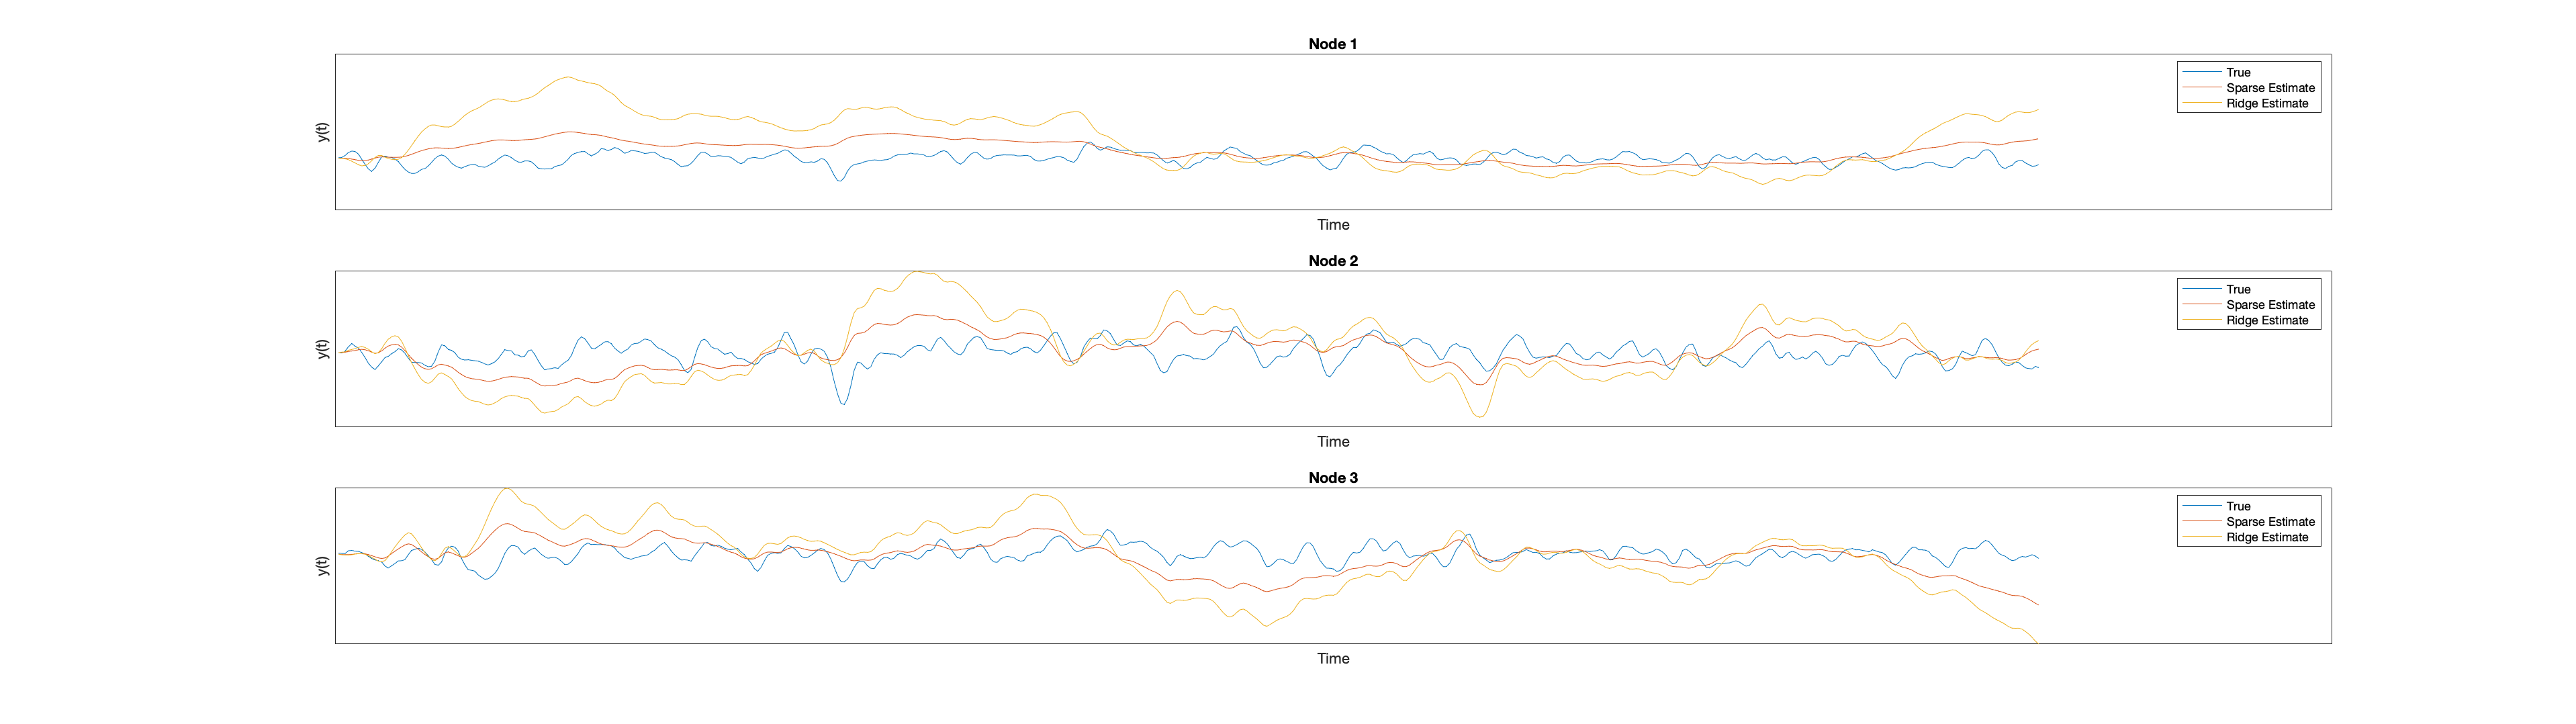

clf
for i = 0:(stim_options.n-1)
    subplot(stim_options.n, 1, i+1);
    cur_y = output_ridge.signal.y_source(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(1:stim_options.T, real(cur_y));
    hold on
    cur_y = output_sparse.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    cur_y = stim_options.TR*cumsum(ifft(cur_y));
    cur_y = [0; cur_y(1:end-1)];
    plot(1:stim_options.T, real(cur_y));
    hold on
    cur_y = output_ridge.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    cur_y = stim_options.TR*cumsum(ifft(cur_y));
    cur_y = [0; cur_y(1:end-1)];
    plot(1:stim_options.T, real(cur_y));
    legend("True","Sparse Estimate","Ridge Estimate")
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    title(sprintf("Node %.0f", i+1))
    xlabel('Time');
    ylabel('y(t)');
end

## Longer timeseries

What if we gave the model a lot more data (i.e. longer time series).

stim_options.T = stim_options.T*10;

stim_options = struct with fields:
             T: 5120
            TR: 2
             n: 3
       ar_coef: 0.5000
             A: [3×3 double]
             C: [3×3 double]
     nonlinear: 0
     two_state: 0
    stochastic: 1
        centre: 1
       induced: 1
            Tp: [1×1 struct]
           SNR: 3
             a: [3×3 double]
             c: [3×1 double]


[DCM, options] = make_DEM_demo_induced_fmri(stim_options);
if isfield(DCM, "U")
    DCM = rmfield(DCM,'U');
end
[output_sparse, options_sparse] = tapas_rdcm_estimate(DCM, type, options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


DCM.a = logical(DCM.Tp.A);
[output_ridge, options_ridge] = tapas_rdcm_estimate(DCM, type, options, 1);


Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


Plot results

**Why aren't the priors overwhelmed by more data?**

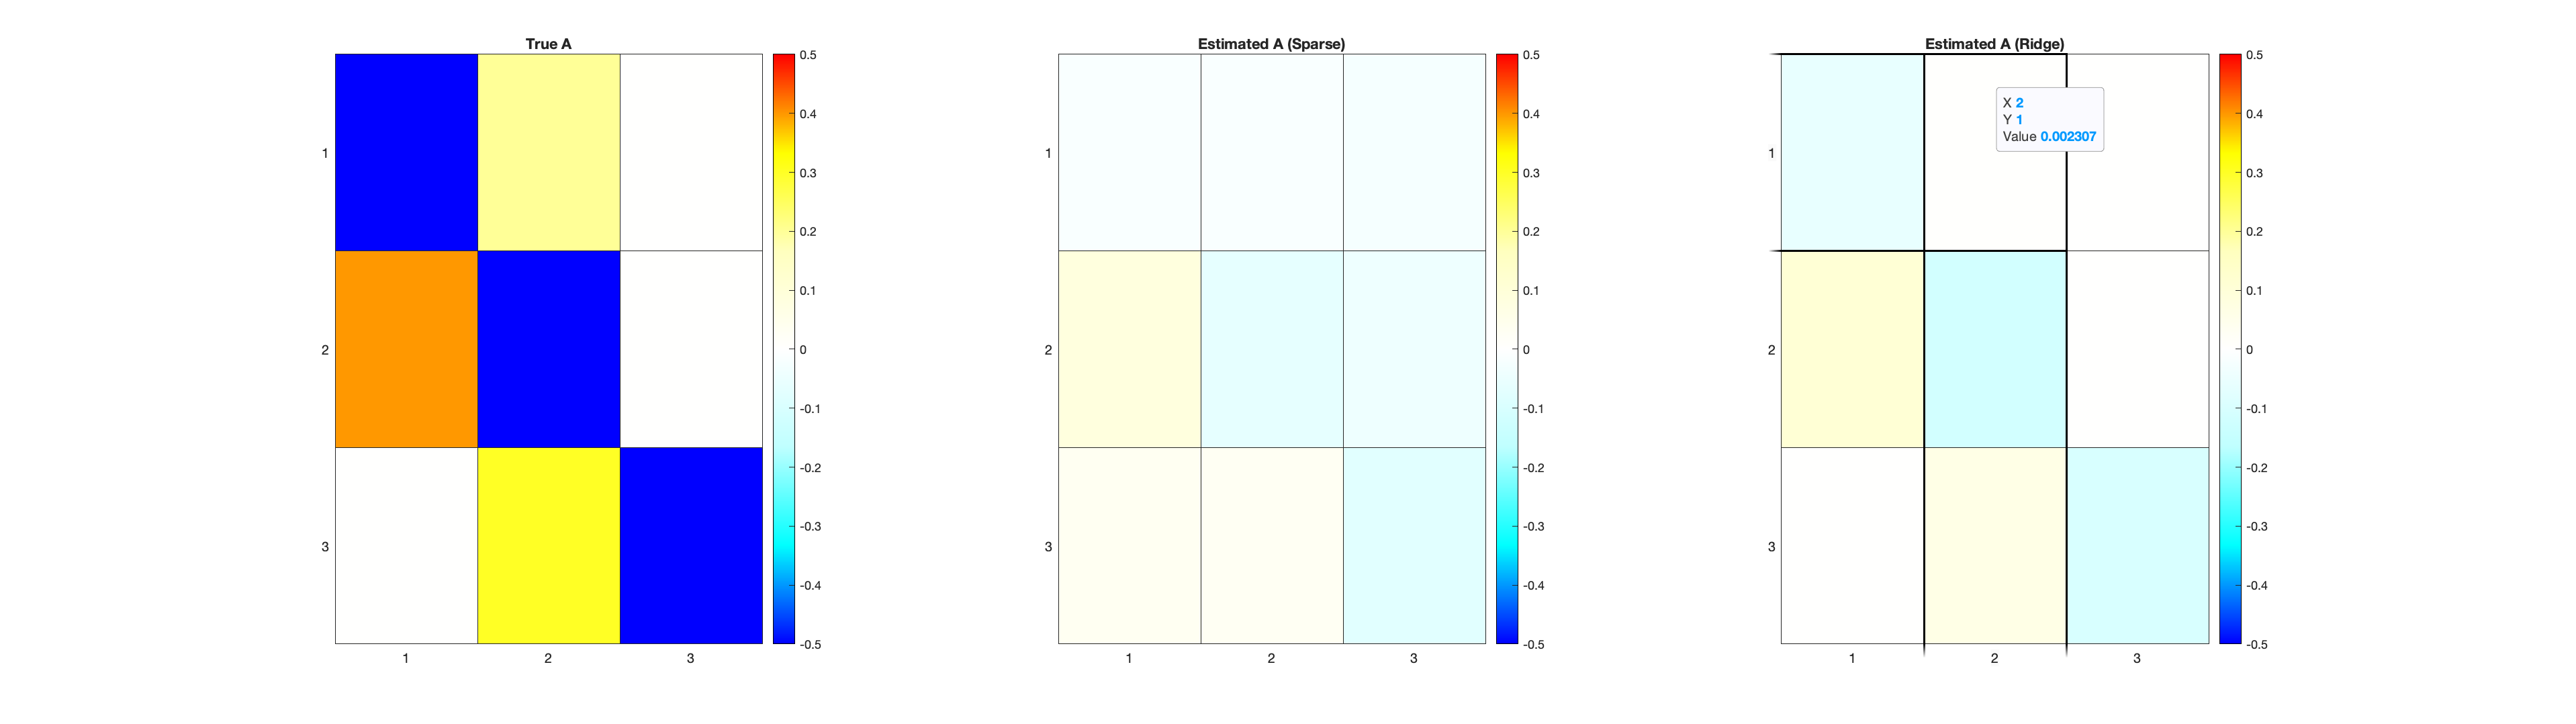

f = figure();

subplot(1, 3, 1)
h = heatmap(DCM.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A"); 

subplot(1, 3, 2)
h = heatmap(output_sparse.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("Estimated A (Sparse)"); 

subplot(1, 3, 3)
h = heatmap(output_ridge.Ep.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("Estimated A (Ridge)"); 

set(f,'Units','normalized','Position',[0 0 1 .5]); 

Predicted vs. actual in frequency domain

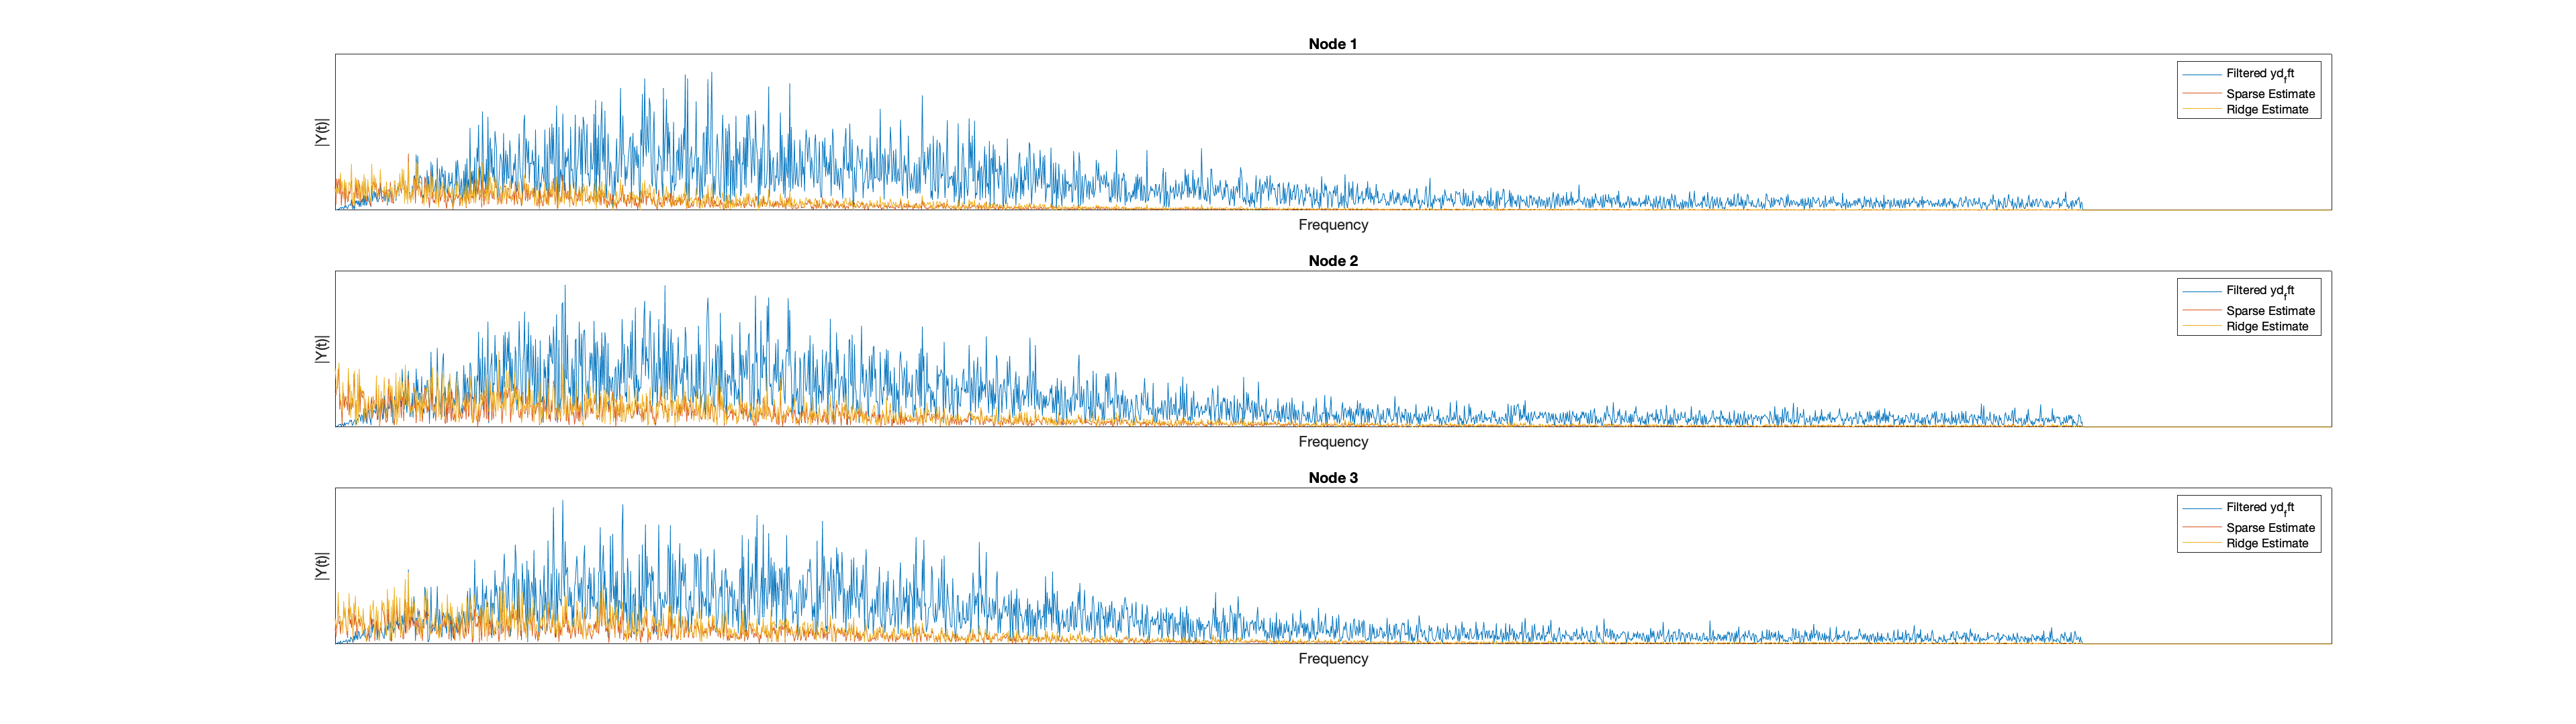

real_comps = 1:(ceil((length(DCM.Y.y)+1)/2));
Fs = options.y_dt;
sampnum = [0: max(real_comps)-1]';
f = sampnum*Fs/length(DCM.Y.y);
clf
for i = 0:(stim_options.n-1)
    subplot(stim_options.n, 1, i+1);
    cur_y = output_ridge.signal.yd_source_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    hold on
    cur_y = output_sparse.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    hold on
    cur_y = output_ridge.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(f, abs(cur_y(real_comps)));
    legend("Filtered yd_\fft","Sparse Estimate","Ridge Estimate");
    set(gca,'XTick',[]);
    set(gca,'YTick',[]);
    title(sprintf("Node %.0f", i+1));
    ylabel('|Y(t)|');
    xlabel('Frequency');
end

Predicted vs. actual in time domain

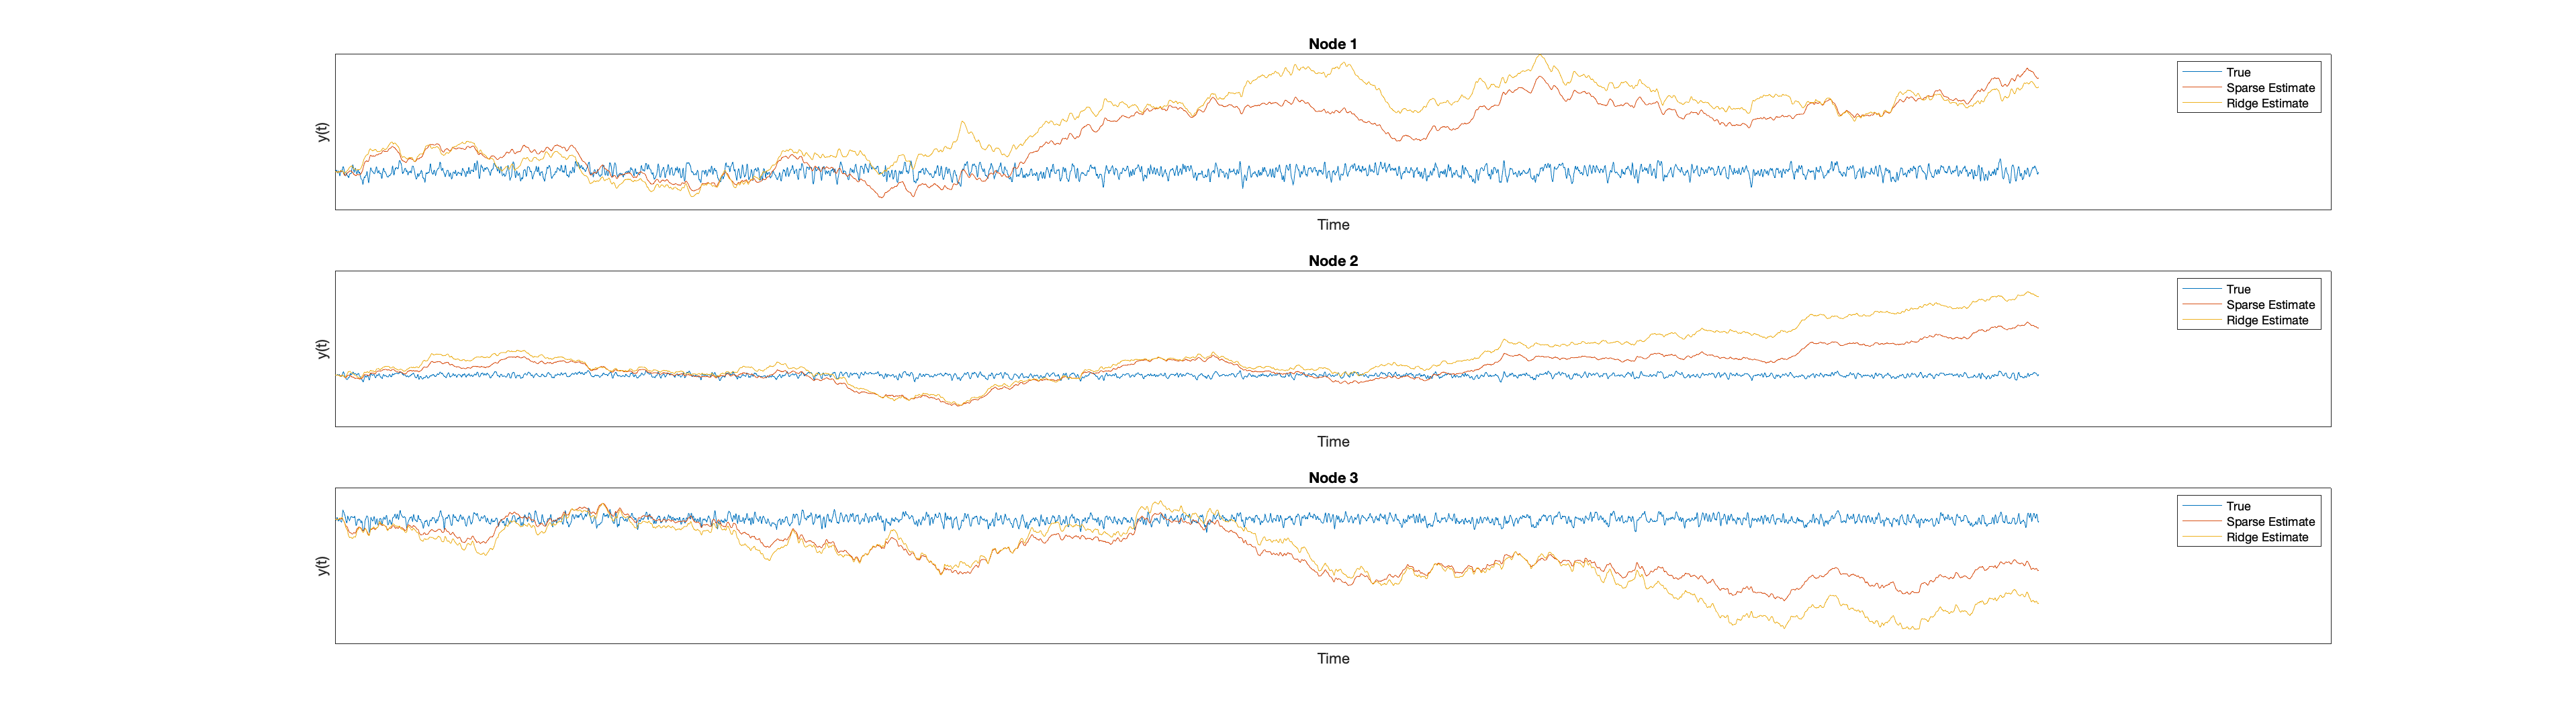

clf
for i = 0:(stim_options.n-1)
    subplot(stim_options.n, 1, i+1);
    cur_y = output_ridge.signal.y_source(i*stim_options.T+1:(i+1)*stim_options.T);
    plot(1:stim_options.T, real(cur_y));
    hold on
    cur_y = output_sparse.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    cur_y = stim_options.TR*cumsum(ifft(cur_y));
    cur_y = [0; cur_y(1:end-1)];
    plot(1:stim_options.T, real(cur_y));
    hold on
    cur_y = output_ridge.signal.yd_pred_rdcm_fft(i*stim_options.T+1:(i+1)*stim_options.T);
    cur_y = stim_options.TR*cumsum(ifft(cur_y));
    cur_y = [0; cur_y(1:end-1)];
    plot(1:stim_options.T, real(cur_y));
    legend("True","Sparse Estimate","Ridge Estimate")
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    title(sprintf("Node %.0f", i+1))
    xlabel('Time');
    ylabel('y(t)');
end

Where to the estimates of variances of connectivity parameters live? Can I visualize the change from the prior to the posterior of this distribution?

Due to Variational Bayes with Laplace the posterior will be normal. 

This might help answer why priors on the connectivity parameter means are not overwhelmed by more data.

contains a column of cells for each node in the network. Each cell contains a variance covariance matrix for all estimated parameters (including 0's for B?)